flux_period = 1109.6;   %mv across a 10kohm resistor
gate_period=51.2859;    % mV
restot=13 ;   %kohms
Ej=calculate_Ej_given_Rn(restot/2);
Ej=Ej*1e9;
Ej=14e9;
csigma=413*70*75/50/50; %aF
Cg=6.4e-18;
Ec=calculate_Ec_from_c_sigma(csigma);
Ec=Ec*1e9

Ec = 2.2274e+10

Ec=53e9;
%charge_states=2; always 2. 2 charge state model
number_points=6;    %number of points around the experimental flux and gate points used to calculate derivatives
if number_points>11  
    disp('error')
    return
end
% Ej=Ej*Ec;
    E1=[];
    dE1=[];
    flux=[];
    gate=[];
    dE1squared=[];  
    dE1cubed=[];
    dE1fourth=[];
    freq_shift=[];
    E2=[];
    a=[];
    b=[];
    flux_values_1=[];
    gate_values_1=[];
 
a=linspace(-3*pi/2,3*pi/2,100);
b=linspace(0,2,100);   %gate has to lie between 0 and 2
% a=linspace(-2.269,1.695,100);
% b=linspace(-1.488,.8608,100);
gate_values_1=b;
flux_values_1=a;

 %%%%%  decides whether to plot eigenenergies or not %%%%%%%%%%%
    if ~exist('plot_display','var')
        plot_display=1;
    end
   

 %%%%%%%%% generate gate and flux values from experimental values %%%%%%%%
    delta_0=0.088;
    gate_spacing=diff(gate_values_1);
    if ~mean(gate_spacing)==gate_spacing(1)
        return
    end
    gate_spacing=gate_spacing(1);
    flux_spacing=diff(flux_values_1);
    if ~mean(flux_spacing)==flux_spacing(1)
        return
    end
    flux_spacing=flux_spacing(1);
    gate=[];
    flux=[];
    flux_spacing=flux_spacing(1);
%     for i=1:length(gate_values_1)
%         gate_temp=linspace(gate_values_1(i)-number_points*gate_spacing/20,gate_values_1(i)+number_points*gate_spacing/20,2*number_points+1);
%         gate=[gate,gate_temp];
%     end
    gate=gate_values_1;
    for i=1:length(flux_values_1)
        flux_temp=linspace(flux_values_1(i)-number_points*flux_spacing/20,flux_values_1(i)+number_points*flux_spacing/20,2*number_points+1);
        flux=[flux,flux_temp];
    end
%     for i=1:length(gate_values_1)-1
%         gate_temp=linspace(gate_values_1(i),gate_values_1(i+1),6);
%         gate_temp=gate_temp(1:end-1);
%         gate=[gate,gate_temp];
%     end
%     gate_positive=gate(gate>0);
%     c=length(gate_positive);
%     gate_negative=gate(gate<0);
%     d=length(gate_negative);
%     gate=[gate_negative+gate(1),gate,gate_positive+gate(end)];
%     gate_temp=linspace(gate_values(1)-3*gate_spacing,gate_values(1),4);
%     gate_temp=gate_temp(1:end-1);
%     gate=[gate_temp,gate];
%     gate_temp=linspace(gate_values(end),gate_values(end)+8*gate_spacing,9);
%     gate=[gate,gate_temp];
%     for i=1:length(flux_values_1)-1
%         flux_temp=linspace(flux_values_1(i),flux_values_1(i+1),6);
%         flux_temp=flux_temp(1:end-1);
%         flux=[flux,flux_temp];
%     end
%     flux_temp=linspace(flux_values(1)-3*flux_spacing,flux_values(1),4);
%     flux_temp=flux_temp(1:end-1);
%     flux=[flux_temp,flux];
%     flux_temp=linspace(flux_values(end),flux_values(end)+8*flux_spacing,9);
%     flux=[flux,flux_temp]
%     flux_positive=flux(flux>0);
%     a=length(flux_positive);
%     flux_negative=flux(flux<0);
%     b=length(flux_negative);
%     flux=[flux_negative+flux(1),flux,flux_positive+flux(end)];
%     figure
%     plot(flux)
%     title('flux values')
%     figure
%     plot(gate)
%     title('gate values')
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
 

  E1=zeros(length(flux),length(gate));
    for i=1:length(gate)
      for j=1:length(flux)
          E1(j,i)=-sqrt(4*Ec^2*(1-gate(i))^2+Ej^2*(cos(flux(j))^2)+(Cg^2/csigma^2)*sin(flux(j)).^2);
          E2(j,i)=sqrt(4*Ec^2*(1-gate(i))^2+Ej^2*(cos(flux(j))^2)+(Cg^2/csigma^2)*sin(flux(j)).^2);
      end
  end

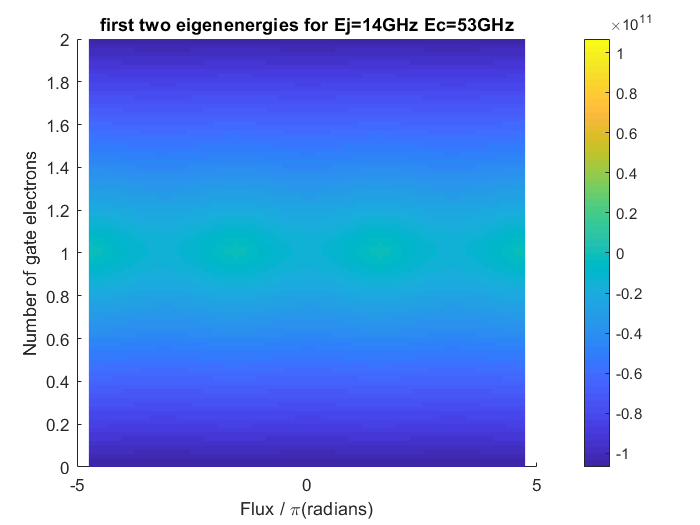


     %%%%%%%%%%%%%% plot eigenenergies if needed %%%%%%%%%%%%%%
    if plot_display==1
        figure
        hold on
        q=surf(gate,flux,E1);
        xlabel('Number of gate electrons');
        ylabel('Flux / \pi(radians)');
        zlabel('E (Hz)');
        set(q,'LineStyle','none');
        w=surf(gate,flux,E2);
        view(90,270);
        tit=['first two eigenenergies for Ej=' num2str(Ej/1e9) 'GHz Ec=' num2str(Ec/1e9) 'GHz'];
        title(tit);
        set(w,'LineStyle','none'); 
        colorbar
        hold off
    end

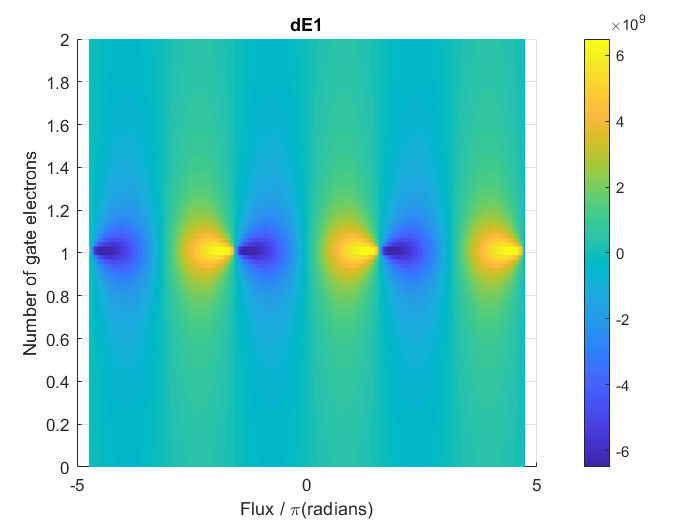

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

    %%%%%%% initiate arrays for derivatives %%%%%%%%%%%%
    dE1=ones(size(E1));
    dE1squared=ones(size(E1));
    dE1cubed=ones(size(E1));
    dE1fourth=ones(size(E1));
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    
    %%%%%%%%%% calculate first 4 derivatives & freq shifts %%%%%%%%%%%%%%%%%%%%%%%%
    for i=1:length(gate)
        for j=1:length(flux)
            dE1(j,i)=(Ej^2/2*sin(2*flux(j))*(-1+(Cg^2/csigma^2)))/2/E1(j,i);
%             dE1(j,i)=dE1(j,i)*2;
            dE1squared(j,i)=1/2/E1(j,i)*(Ej^2/2*cos(2*flux(j))*(-1+(Cg^2/csigma^2)))-1/E1(j,i).*dE1(j,i)^2;
        end
    end    
%     dE1squared=dE1squared*4;
    freq_shift=dE1squared.*delta_0^2;%+1/2*dE1fourth.*delta_0^4;
%     freq_shift=freq_shift(b+1:end-a+1,d+1:end-c+1);
%     dE1=dE1(b+1:end-a+1,d+1:end-c+1);
%     dE1squared=dE1squared(b+1:end-a+1,d+1:end-c+1);
%     dE1cubed=dE1cubed(b+1:end-a+1,d+1:end-c+1);
%     dE1fourth=dE1fourth(b+1:end-a+1,d+1:end-c+1);
%     gate=gate(d+1:end-c+1)
%     flux=flux(b+1:end-a+1)
%     difference=diff(flux)
%     mean(difference)
%     flux_values_angle
%     diff(flux_values_angle)
%     gate_values_number
  %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    figure
    r=surf(gate,flux,dE1);
    set(r,'LineStyle','none');
    view(90,270)
    xlabel('Number of gate electrons');
    ylabel('Flux / \pi(radians)');
    zlabel('dE1');
    colorbar
    title('dE1')

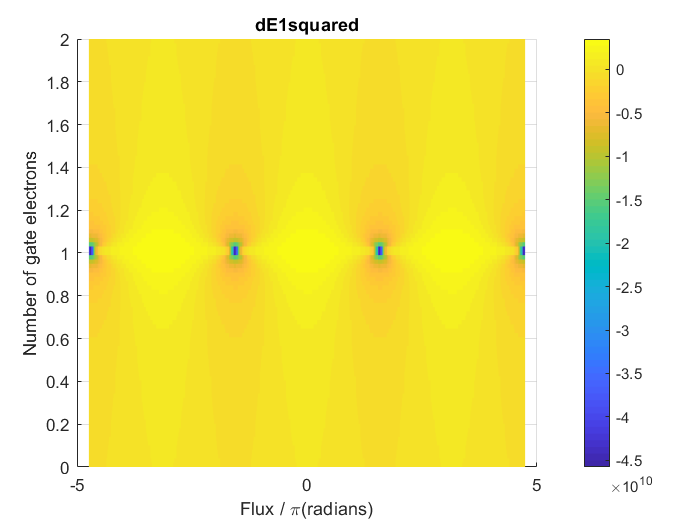

    
    figure
    r=surf(gate,flux,dE1squared);
    set(r,'LineStyle','none');
    view(90,270)
    xlabel('Number of gate electrons');
    ylabel('Flux / \pi(radians)');
    zlabel('dE1dquared');
    colorbar
    title('dE1squared')

    
%     figure
%     r=surf(gate,flux,dE1cubed);
%     set(r,'LineStyle','none');
%     view(90,270)
%     xlabel('Number of gate electrons');
%     ylabel('Flux / \pi(radians)');
%     zlabel('dE1cubed');
%     colorbar
%     title('dE1cubed')
%     
%     figure
%     r=surf(gate,flux,dE1fourth);
%     set(r,'LineStyle','none');
%     view(90,270)
%     xlabel('Number of gate electrons');
%     ylabel('Flux / \pi(radians)');
%     zlabel('dE1fourth');
%     colorbar
%     title('dE1fourth')
   

 
    freq_shift_reshaped=reshape(freq_shift,[length(flux)*length(gate),1]);
    figure
    r=surf(gate,flux,freq_shift);
    set(r,'LineStyle','none');
    view(90,270)
    xlabel('Number of gate electrons');
    ylabel('Flux / \pi(radians)');
    zlabel('freq_shift');
    colorbar
    mean(freq_shift_reshaped)

ans = -2.0847e+05

    std(freq_shift_reshaped)

ans = 1.4840e+07

    mean(freq_shift_reshaped)-2*abs(std(freq_shift_reshaped))

ans = -2.9889e+07

    mean(freq_shift_reshaped)+2*abs(std(freq_shift_reshaped))

ans = 2.9472e+07

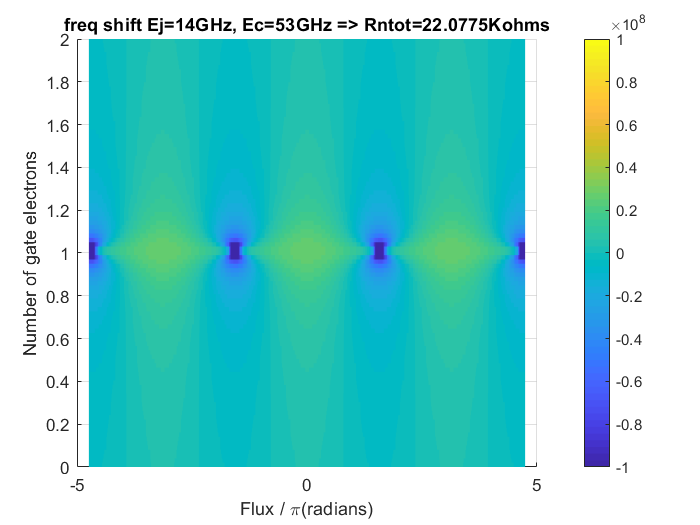

%     axis([gate_values_1(1) gate_values_1(end) flux_values_1(1) flux_values_1(end) mean(freq_shift_reshaped)-2*abs(std(freq_shift_reshaped)) mean(freq_shift_reshaped)+2*abs(std(freq_shift_reshaped))])
%     caxis([mean(freq_shift_reshaped)-2*abs(std(freq_shift_reshaped))     mean(freq_shift_reshaped)+2*abs(std(freq_shift_reshaped))])
    caxis([-1e8 1e8])
    h=6.626e-34;
    e=1.6e-19;
    Tc=1.2;
    Rn=calculate_Rn_given_Ej(Ej/1e9);
    Rn=Rn*2;
    title(['freq shift Ej=' num2str(Ej/1e9) 'GHz, Ec=' num2str(Ec/1e9) 'GHz => Rntot=' num2str(Rn) 'Kohms'])

%     for j=1:3:length(gate_values_1)
% %         j=randi(length(flux_values_1));
%         figure
%         plot(flux_values_1,freq_shift(:,j)/1e6)
%         title(['freq shift for gate=' num2str(gate_values_1(j)) 'electrons']);
%         xlabel('Flux / \pi(Radians)');
%         ylabel('Freq shift (MHz)');
%     end

%     for i=1:3:length(flux_values_1)
%         figure
%         plot(gate_values_1,freq_shift(i,:)/1e6)
%         title(['freq shift for flux=' num2str(flux_values_1(i)) ' *\pi']);
%         xlabel('Gate number of electrons');
%         ylabel('Freq shift (MHz)')
%     end

    %%%%%%%%%%%%%%%%
    %troubleshooting
    % E1(1,1)
    % E2(1,1)   
    % eigenvalue(1,1,1)
    % eigenvalue(2,1,1)
%     H(:,:,1,1)
    % eig(H(:,:,1,1))
    % (1-gate(1)/2)^2
    % (2-gate(1)/2)^2
    % (3-gate(1)/2)^2
    % (4-gate(1)/2)^2
    % (5-gate(1)/2)^2
    % -Ej*cos(flux(1))
    %%%%%%%%%%%%%%%%%%%%
    
 
